### **Parameters**

f = 3;
uJ = 0.75;
uA = 0.75;
mo = 2.5;
mb = 0.2;


## Stability isocline: f

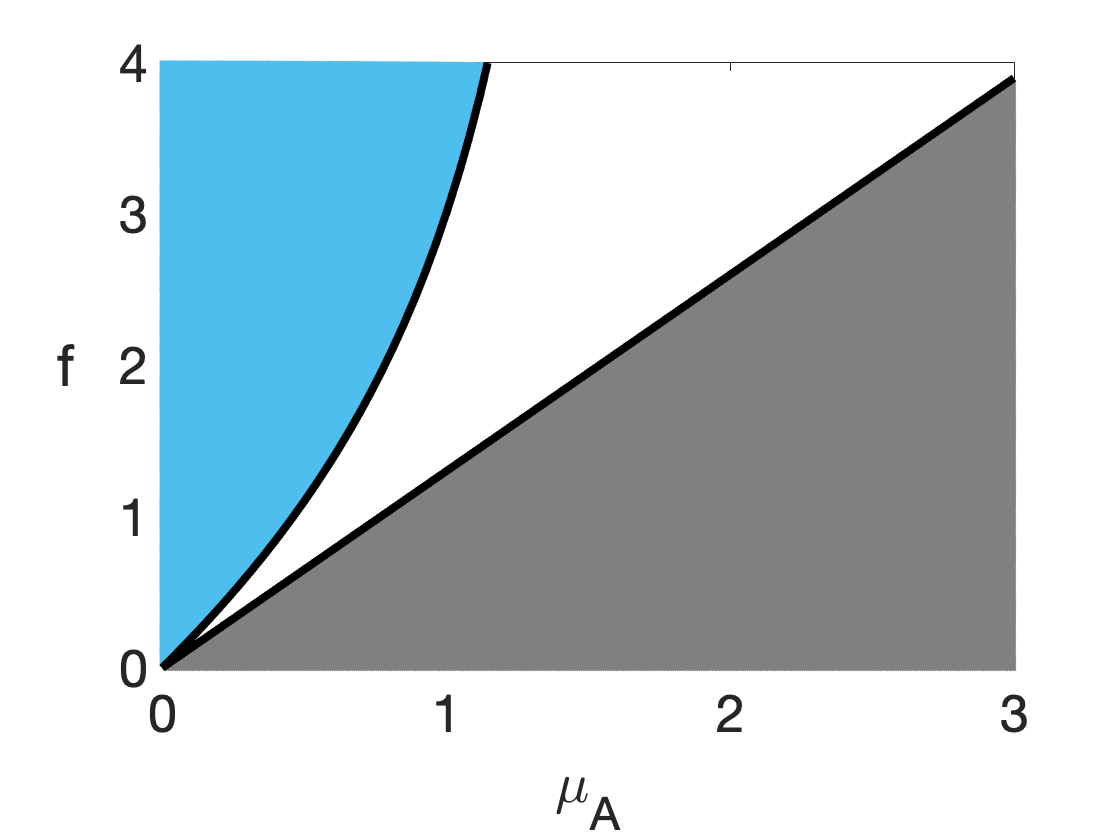

%% f >= uA*(mo+uJ-uA)/(mo-uJ-uA)
%% f > uA
%% f > uA*(uJ/mo+1)

%% Figure 1F 
ymin = 0;
ymax = 4;
fplot(@(x) x.*(mo+uJ-x)./(mo-uJ-x),[0,1.7],'LineWidth',4,'Color','k')
hold on
for y = ymin:0.01:ymax
   fplot(@(x) y+x.*(mo+uJ-x)./(mo-uJ-x),[0,1.7],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330]) 
end
for y = ymin:0.01:ymax
   fplot(@(x) x.*(mo+uJ)./mo-y,[0,3],'LineWidth',4,'Color',[0.5, 0.5, 0.5]) 
end
fplot(@(x) x.*(mo+uJ-x)./(mo-uJ-x),[0,1.7],'LineWidth',4,'Color','k')
fplot(@(x) x.*(mo+uJ)./mo,[0,3],'LineWidth',4,'Color','k')
ylabel("f      ")
xlabel("\mu_A")
set(gca, 'FontSize', 26)
ylim([ymin ymax])
%text(0.9,1.85,"Stable",'FontSize',30)
%text(0.05,2.75,"Unstable",'FontSize',28)
%text(1.25,0.3,"Extinction",'FontSize',30,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off

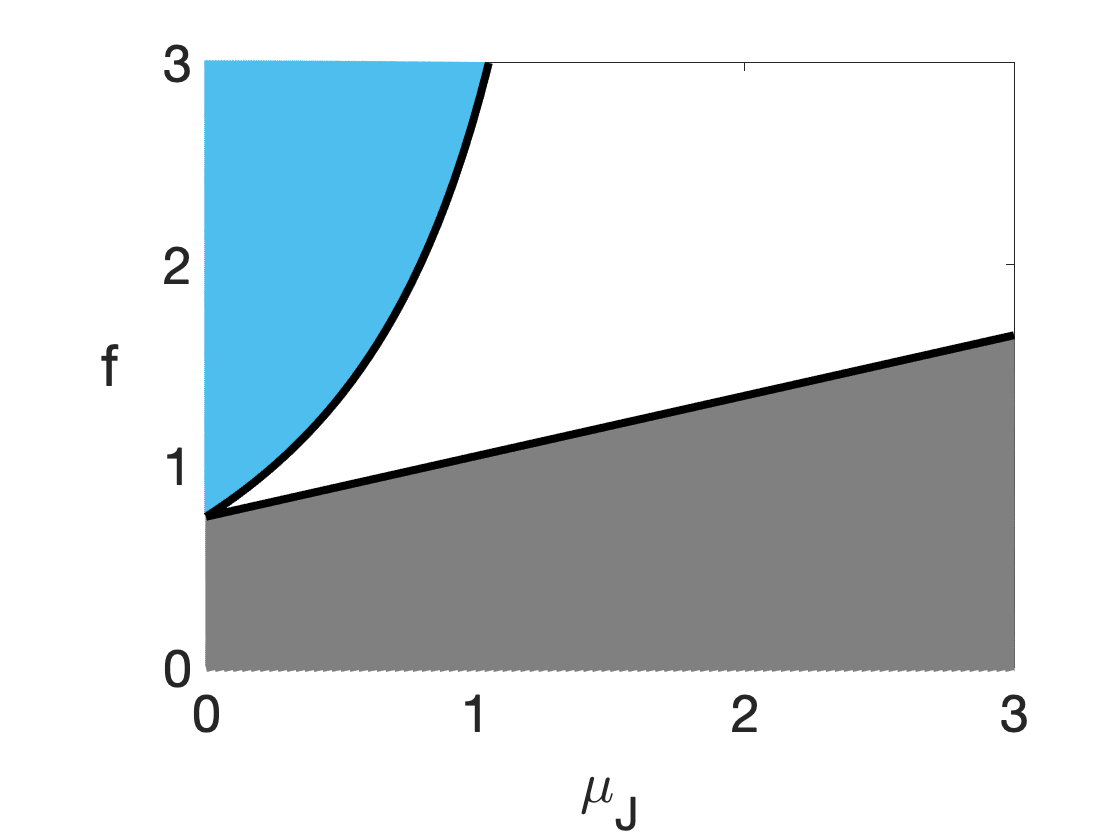



%% Figure 1D
fplot(@(x) uA.*(mo+x-uA)./(mo-x-uA),[0,1.4],'LineWidth',4,'Color','k')
hold on
ymin = 0;
ymax = 3;
for y = ymin:0.01:ymax
    fplot(@(x) y+uA.*(mo+x-uA)./(mo-x-uA),[0,1.4],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330])
end
for y = ymin:0.01:ymax
    fplot(@(x) uA.*(x./mo+1)-y,[0,3],'LineWidth',4,'Color',[0.5, 0.5, 0.5])
end
fplot(@(x) uA.*(mo+x-uA)./(mo-x-uA),[0,1.4],'LineWidth',4,'Color','k')
fplot(@(x) uA.*(x./mo+1),[0,3],'LineWidth',4,'Color','k')
ylabel("f      ")
xlabel("\mu_J")
set(gca, 'FontSize', 26)
ylim([ymin ymax])
%text(0.75,1.5,"Stable",'FontSize',30)
%text(0.05,2.5,"Unstable",'FontSize',28)
%text(1.5,0.4,"Extinction",'FontSize',30,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off

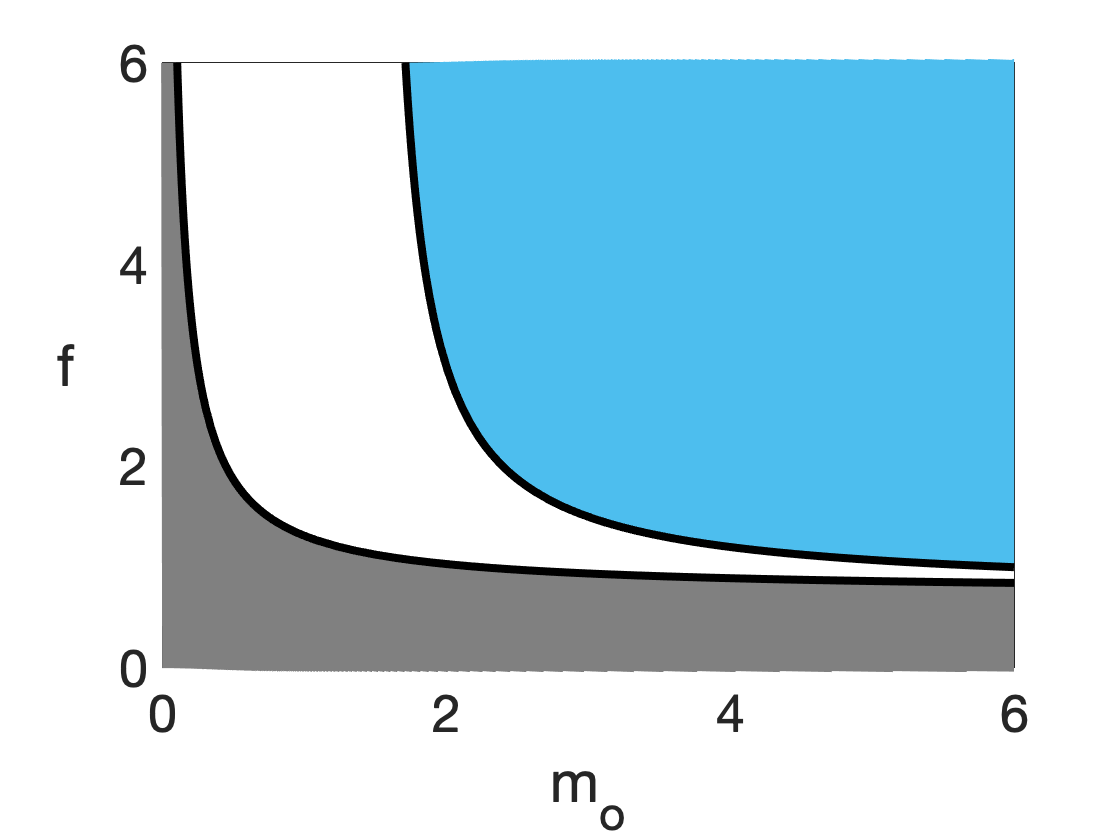



%% Figure 1C
%Here I am only plotting to the right of the asymptote which occurs at
%mo=uJ+uA; to the left of the asymptote, f<=0
fplot(@(x) uA.*(x+uJ-uA)./(x-uJ-uA),[uJ+uA+0.00001,6],'LineWidth',4,'Color','k')
hold on
ymin = 0;
ymax = 6;
for y = ymin:0.01:ymax
    fplot(@(x) y+uA.*(x+uJ-uA)./(x-uJ-uA),[uJ+uA+0.00001,6],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330])
end
for y = ymin:0.01:20
    fplot(@(x) uA.*(uJ./x+1)-y,[0,6],'LineWidth',4,'Color',[0.5, 0.5, 0.5])
end
fplot(@(x) uA.*(x+uJ-uA)./(x-uJ-uA),[uJ+uA+0.00001,6],'LineWidth',4,'Color','k')
fplot(@(x) uA.*(uJ./x+1),[0,6],'LineWidth',4,'Color','k')
ylabel("f      ")
xlabel("m_o")
ylim([ymin ymax])
set(gca, 'FontSize', 26)
%text(0.5,3,"Stable",'FontSize',30)
%text(3,5,"Unstable",'FontSize',30)
%text(2.25,0.5,"Extinction",'FontSize',30,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off

## Stability isocline: mo

%% mo >= (uA*(f-uA)+uJ*(f+uA))/(f-uA)
%% mo > uA*uJ/(f-uA)



## Stability isocline: uJ

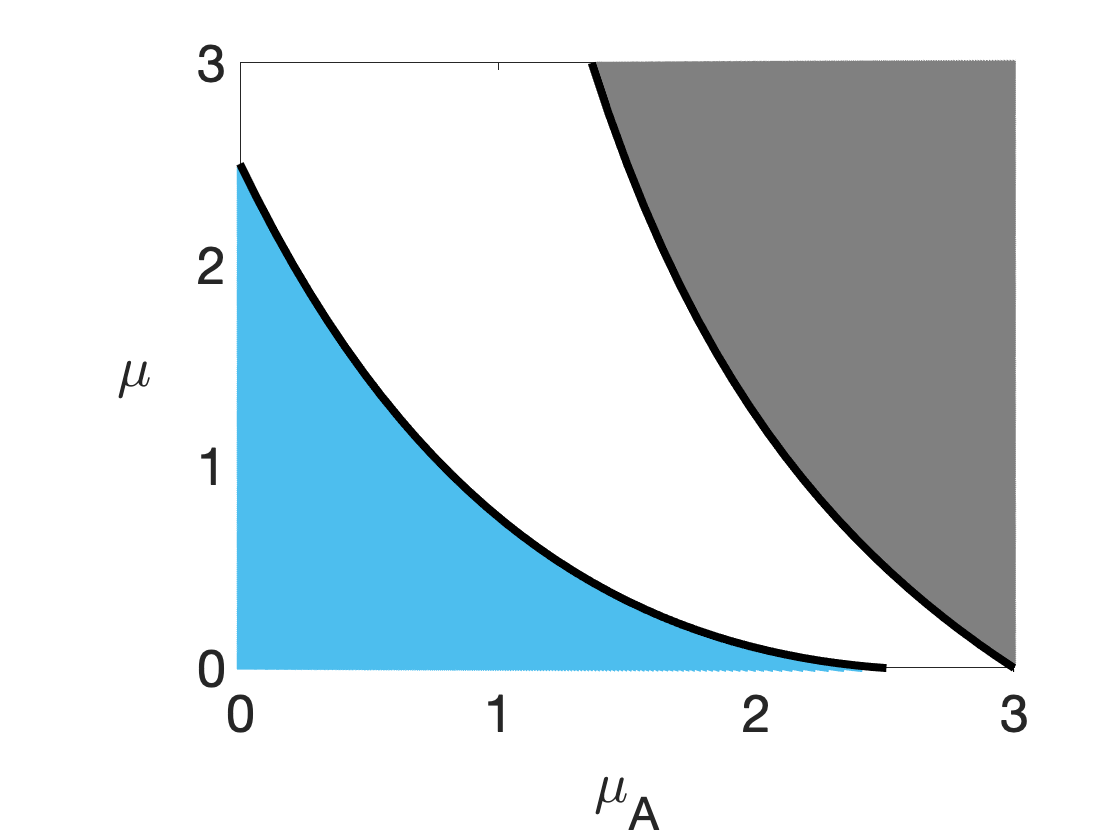

%% uJ <= (f-uA)*(mo-uA)/(f+uA)
%% uJ < mo*(f-uA)/uA

%% Figure 1E
fplot(@(x) (f-x).*(mo-x)./(f+x),[0,3],'LineWidth',4,'Color','k')
hold on
ymin = 0;
ymax = 3;
for y = ymin:0.01:ymax
    fplot(@(x) (f-x).*(mo-x)./(f+x)-y,[0,3],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330])
end
for y = ymin:0.01:ymax
    fplot(@(x) mo.*(f-x)./x+y,[0,3],'LineWidth',4,'Color',[0.5, 0.5, 0.5])
end
fplot(@(x) (f-x).*(mo-x)./(f+x),[0,3],'LineWidth',4,'Color','k')
fplot(@(x) mo.*(f-x)./x,[0,3],'LineWidth',4,'Color','k')
ylabel("\mu       ")  %%\mu_J
xlabel("\mu_A")
set(gca, 'FontSize', 26)
ylim([ymin ymax])
%text(0.7,1.8,"Stable",'FontSize',30)
%text(0.2,0.2,"Unstable",'FontSize',30)
%text(1.8,2.5,"Extinction",'FontSize',28,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off

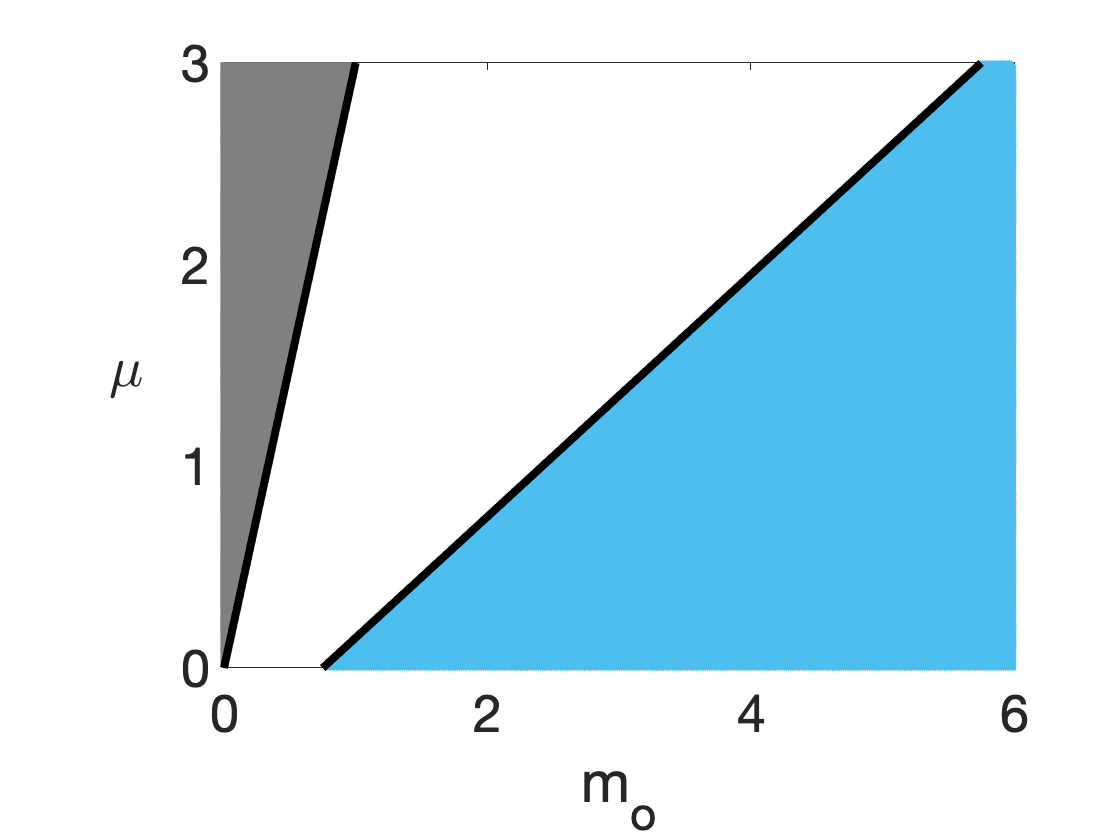



%% Figure 1A
fplot(@(x) (f-uA).*(x-uA)./(f+uA),[0,6],'LineWidth',4,'Color','k')
hold on
ymin = 0;
ymax = 3;
for y = ymin:0.01:3.2
    fplot(@(x) (f-uA).*(x-uA)./(f+uA)-y,[0,6],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330])
end
for y = ymin:0.01:ymax
    fplot(@(x) x.*(f-uA)./uA+y,[0,3],'LineWidth',4,'Color',[0.5, 0.5, 0.5])
end
fplot(@(x) x.*(f-uA)./uA,[0,3],'LineWidth',4,'Color','k')
fplot(@(x) (f-uA).*(x-uA)./(f+uA),[0,6],'LineWidth',4,'Color','k')
ylabel("\mu      ")  %%\mu_J
xlabel("m_o")
set(gca, 'FontSize', 26)
ylim([ymin ymax])
%text(1.75,2.25,"Stable",'FontSize',30)
%text(3,0.75,"Unstable",'FontSize',30)
%text(0.7,0.1,"Extinction",'FontSize',24,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off

## Stability isocline: uA

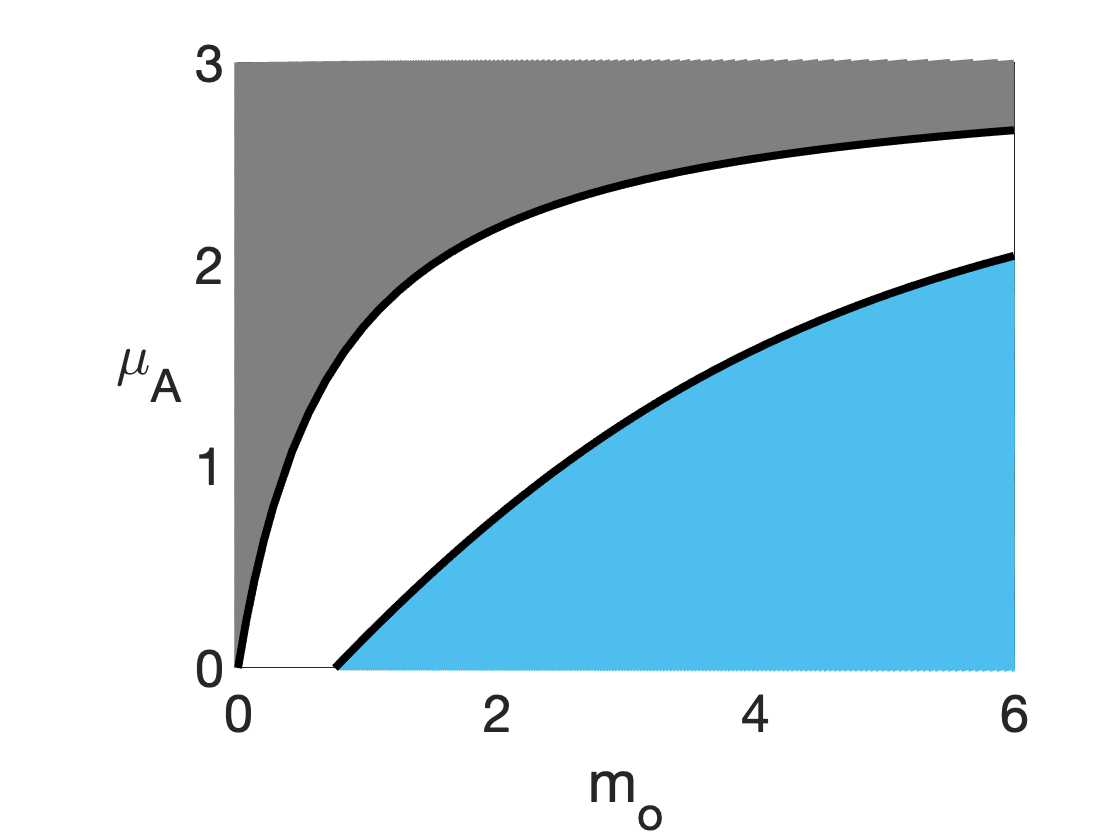

%% uA = (mo+uJ+f)/2 + sqrt((mo+uJ+f)^2 - 4*f*(mo-uJ))/2
%% uA = (mo+uJ+f)/2 - sqrt((mo+uJ+f)^2 - 4*f*(mo-uJ))/2
%% uA < f*mo/(mo+uJ)

%% Figure 1B
fplot(@(x) (x+uJ+f)/2 + sqrt((x+uJ+f).^2 - 4*f.*(x-uJ))/2,[0,6],'LineWidth',4,'Color','k')
hold on
ymin = 0;
ymax = 3;
for y = ymin:0.01:2.5
    fplot(@(x) (x+uJ+f)/2 - sqrt((x+uJ+f).^2 - 4*f.*(x-uJ))/2-y,[0,6],'LineWidth',4,'Color',[0.3010, 0.7450, 0.9330])
end
for y = ymin:0.01:ymax
    fplot(@(x) f.*x./(x+uJ)+y,[0,6],'LineWidth',4,'Color',[0.5, 0.5, 0.5])
end
fplot(@(x) f.*x./(x+uJ),[0,6],'LineWidth',4,'Color','k')
fplot(@(x) (x+uJ+f)/2 - sqrt((x+uJ+f).^2 - 4*f.*(x-uJ))/2,[0,6],'LineWidth',4,'Color','k')
ylabel("\mu_A     ")
xlabel("m_o")
set(gca, 'FontSize', 26)
ylim([ymin ymax])
%text(2.1,1.75,"Stable",'FontSize',30)
%text(3,0.5,"Unstable",'FontSize',30)
%text(1,2.75,"Extinction",'FontSize',30,'Color',"w")
hYLabel = get(gca,'YLabel');
set(hYLabel,'rotation',0,'VerticalAlignment','middle')
hold off